% Set up
clc;
close all;
clear;

## load data

## Re-organize data(eeg)

The data is set to m*n matrix

m = number of epochs

n = Frequency of Sampling * epoch length

test = 1

test = 1

EEG1 = []


EEG1 =

     []



EEG2 = []


EEG2 =

     []



STAGE = []


STAGE =

     []



train = 1:10

train =      1     2     3     4     5     6     7     8     9    10


train(train == test) = [];
for n = train
    edfFilename = sprintf('R%d_edf.mat', n);
    xmlFilename = sprintf('R%d_xml.mat', n);
    load(edfFilename);
    load(xmlFilename);
    hdr.label
    % We can know from the hdr that the 3rd and the 8th 
    % channel of the record is EEG signal
    Fs = hdr.samples(3);
    % every epoch lasts for epochLength seconds (30 seconds)
    numberOfEpochs = length(record(3,:)')/(Fs*epochLength)-1;   % cut the last epoch
    % Initialization of eeg1 and eeg2
    eeg1 = zeros(numberOfEpochs,Fs*epochLength);
    eeg2 = zeros(numberOfEpochs,Fs*epochLength);
    epochAmount = 1;    % How much epoches to cut for one row
    for i = 1:numberOfEpochs
        epochNumber = i;    % start epoch No.
        epochStart = epochNumber*Fs*epochLength;    % will cut the first epoch
        epochEnd = epochStart + epochAmount*Fs*epochLength - 1; % not include the end index
        t = linspace(0,epochAmount*30,epochAmount*Fs*epochLength);
        eeg1(i,:) = record(8,epochStart:epochEnd);
        eeg2(i,:) = record(3,epochStart:epochEnd);
    end
    EEG1 = [EEG1;eeg1];
    EEG2 = [EEG2;eeg2];
    % process the stages
    stages_epoch = zeros(1,numberOfEpochs);
    for i = 1:numberOfEpochs
        stages_epoch(i) = stages(i*30);
    end
    STAGE = [STAGE,stages_epoch];
end

ans = 1×14 cell 数组
    {'SaO2'}    {'HR'}    {'EEGsec'}    {'ECG'}    {'EMG'}    {'EOGL'}    {'EOGR'}    {'EEG'}    {'THORRES'}    {'ABDORES'}    {'POSITION'}    {'LIGHT'}    {'AIRFLOW'}    {'OXstat'}


ans = 1×14 cell 数组
    {'SaO2'}    {'HR'}    {'EEGsec'}    {'ECG'}    {'EMG'}    {'EOGL'}    {'EOGR'}    {'EEG'}    {'THORRES'}    {'ABDORES'}    {'POSITION'}    {'LIGHT'}    {'NEWAIR'}    {'OXstat'}


ans = 1×14 cell 数组
    {'SaO2'}    {'HR'}    {'EEGsec'}    {'ECG'}    {'EMG'}    {'EOGL'}    {'EOGR'}    {'EEG'}    {'THORRES'}    {'ABDORES'}    {'POSITION'}    {'LIGHT'}    {'NEWAIR'}    {'OXstat'}


ans = 1×14 cell 数组
    {'SaO2'}    {'HR'}    {'EEGsec'}    {'ECG'}    {'EMG'}    {'EOGL'}    {'EOGR'}    {'EEG'}    {'THORRES'}    {'ABDORES'}    {'POSITION'}    {'LIGHT'}    {'AIRFLOW'}    {'OXstat'}


ans = 1×14 cell 数组
    {'SaO2'}    {'HR'}    {'EEGsec'}    {'ECG'}    {'EMG'}    {'EOGL'}    {'EOGR'}    {'EEG'}    {'THORRES'}    {'ABDORES'}    {'POSITION'}    {'LIGHT'}    {'NEWAIR'}    {'OXstat'}


ans = 1×14 cell 数组
    {'SaO2'}    {'HR'}    {'EEGsec'}    {'ECG'}    {'EMG'}    {'EOGL'}    {'EOGR'}    {'EEG'}    {'THORRES'}    {'ABDORES'}    {'POSITION'}    {'LIGHT'}    {'AIRFLOW'}    {'OXstat'}


ans = 1×14 cell 数组
    {'SaO2'}    {'HR'}    {'EEGsec'}    {'ECG'}    {'EMG'}    {'EOGL'}    {'EOGR'}    {'EEG'}    {'THORRES'}    {'ABDORES'}    {'POSITION'}    {'LIGHT'}    {'NEWAIR'}    {'OXstat'}


ans = 1×14 cell 数组
    {'SaO2'}    {'HR'}    {'EEGsec'}    {'ECG'}    {'EMG'}    {'EOGL'}    {'EOGR'}    {'EEG'}    {'THORRES'}    {'ABDORES'}    {'POSITION'}    {'LIGHT'}    {'NEWAIR'}    {'OXstat'}


ans = 1×14 cell 数组
    {'SaO2'}    {'HR'}    {'EEGsec'}    {'ECG'}    {'EMG'}    {'EOGL'}    {'EOGR'}    {'EEG'}    {'THORRES'}    {'ABDORES'}    {'POSITION'}    {'LIGHT'}    {'NEWAIR'}    {'OXstat'}


## Plot for check

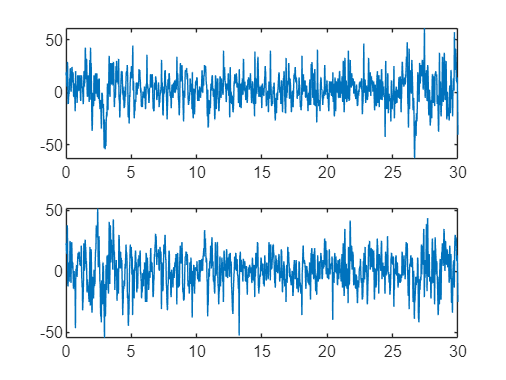

% Plot the first epoch
figure(1)
subplot(2,1,1)
plot(t,EEG1(1,:))
subplot(2,1,2)
plot(t,EEG2(1,:))


% FFT to see frequency domain
% N = 1024;
% EEG1 = abs(fftshift(fft(eeg1(1,:),N)));
% fshift=linspace(-0.5*Fs,0.5*Fs,N);     % fftshift x axis
% figure;
% plot(fshift,EEG1)

## Remove the baseline drift

% It will filter every row
EEG1_filtered = baseline_drift_removal(EEG1,Fs,0.5);

EEG2_filtered = baseline_drift_removal(EEG2,Fs,0.5);

## Muscle noise filtering & Power line interference removal

EEG1_filtered = muscle_noise_filtering(EEG1_filtered,Fs,30);

EEG2_filtered = muscle_noise_filtering(EEG2_filtered,Fs,30);

## Check changes in frequency domain

% FFT
% N = 1024;
% EEG1_F = abs(fftshift(fft(eeg1_filtered,N)));
% fshift=linspace(-0.5*Fs,0.5*Fs,N);     % fftshift x axis
% figure;
% plot(fshift,EEG1,fshift,EEG1_F)

## Feature Extraction - Time-domain

features_time_eeg1 = extract_time_features(EEG1_filtered);
features_time_eeg2 = extract_time_features(EEG2_filtered);


feature_labels = {'Mean', 'Variance', 'Skewness', 'Kurtosis', ...
                  'Zero-Crossing Rate', 'Hjorth Activity', ...
                  'Hjorth Mobility', 'Hjorth Complexity'};

disp('Characteristics of EEG1 (Time-Domain):');

Characteristics of EEG1 (Time-Domain):


for i = 1:length(feature_labels)
    fprintf('%s: %.4f\n', feature_labels{i}, features_time_eeg1(i));
end

Mean: 0.0210
Variance: 0.1810
Skewness: -0.2066
Kurtosis: 0.0449
Zero-Crossing Rate: -0.0313
Hjorth Activity: -0.0355
Hjorth Mobility: 0.0293
Hjorth Complexity: -0.1628



disp('Characteristics of EEG2 (Time-Domain):');

Characteristics of EEG2 (Time-Domain):


for i = 1:length(feature_labels)
    fprintf('%s: %.4f\n', feature_labels{i}, features_time_eeg2(i));
end

Mean: 0.0262
Variance: 0.0159
Skewness: -0.0881
Kurtosis: -0.0394
Zero-Crossing Rate: -0.2019
Hjorth Activity: -0.0408
Hjorth Mobility: 0.0099
Hjorth Complexity: -0.1252


## Feature Extraction - Frequency Domain

[features_freq_eeg1, Pxx_eeg1, freqs_eeg1] = extract_freq_features(EEG1_filtered, Fs);
[features_freq_eeg2, Pxx_eeg2, freqs_eeg2] = extract_freq_features(EEG2_filtered, Fs);

feature_labels_freq = {'Power Delta', 'Power Theta', 'Power Alpha', 'Power Beta', 'Power Gamma', ...
                      'Spectral Edge Frequency', ...
                      'Relative Delta', 'Relative Theta', 'Relative Alpha', 'Relative Beta', 'Relative Gamma'};

disp('Characteristics of EEG1 (Frequency-Domain):');

Characteristics of EEG1 (Frequency-Domain):


for i = 1:length(feature_labels_freq)
    fprintf('%s: %.4f\n', feature_labels_freq{i}, features_freq_eeg1(i));
end

Power Delta: 6777.4693
Power Theta: 11229.3600
Power Alpha: 6513.6253
Power Beta: 9211.2052
Power Gamma: 11123.9064
Spectral Edge Frequency: 9768.1778
Relative Delta: 11233.6962
Relative Theta: 5817.6840
Relative Alpha: 9474.2615
Relative Beta: 3117.6757
Relative Gamma: 5575.2584



disp('Characteristics of EEG2 (Frequency-Domain):');

Characteristics of EEG2 (Frequency-Domain):


for i = 1:length(feature_labels_freq)
    fprintf('%s: %.4f\n', feature_labels_freq{i}, features_freq_eeg2(i));
end

Power Delta: 6800.7709
Power Theta: 11995.7519
Power Alpha: 9237.0458
Power Beta: 9757.0650
Power Gamma: 10851.7076
Spectral Edge Frequency: 6514.8886
Relative Delta: 13328.4631
Relative Theta: 4860.2425
Relative Alpha: 10289.2710
Relative Beta: 4212.5765
Relative Gamma: 4973.0364


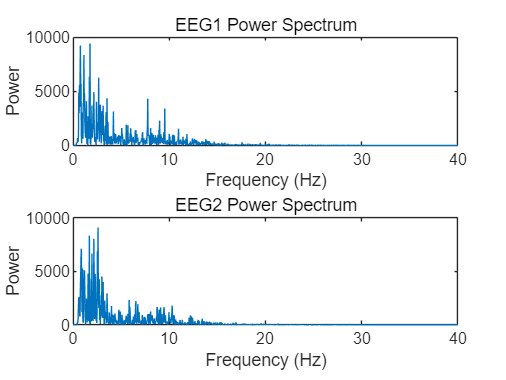


figure;
subplot(2,1,1);
plot(freqs_eeg1, Pxx_eeg1(1,:));
xlabel('Frequency (Hz)');
ylabel('Power');
title('EEG1 Power Spectrum');
xlim([0 40]);

subplot(2,1,2);
plot(freqs_eeg2, Pxx_eeg2(1,:));
xlabel('Frequency (Hz)');
ylabel('Power');
title('EEG2 Power Spectrum');
xlim([0 40]);

## Classification

features = [features_time_eeg1, features_freq_eeg1];
features = normalize(features);
size(features)

ans =         9210          19


labels = categorical(STAGE, [0 1 2 3 4 5], {'REM', 'None', 'N3', 'N2', 'N1', 'Wake'});
size(labels)

ans =            1        9210


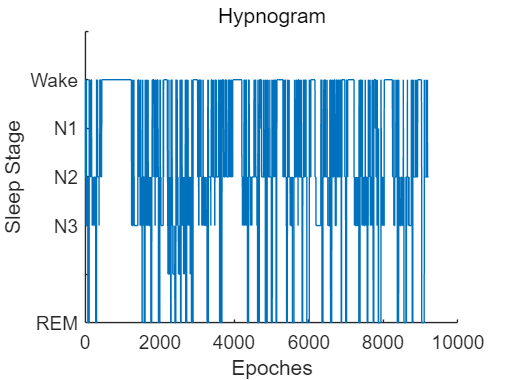


figure;
plot(STAGE); %sleep stages are for 30 seconds epochs
ylim([0 6]);
set(gca,'ytick',0:6,'yticklabel',{'REM','','N3','N2','N1','Wake',''});
xlabel('Epoches');
ylabel('Sleep Stage');
box off;
title('Hypnogram');

set(gcf,'color','w');